# **Derek Chibuzor**

# **AME 404**

# **Project 3**

clear;clc
close all
warning('off', 'all');

## **Import Dataset**

The AI4I 2020 Predictive Maintenance Dataset is an industrial predictive maintenance dataset, comprised of 10,000 observational instances of (unspecified) industrial machines under various conditions. Each observation corresponds to a specific recorded state of a machine during its operation, capturing features such as temperatures, speed, torque, tool wear, and whether a failure has occurred. Each observation is described by 14 features, and the dataset is intended for tasks such as classification, regression, and causal discovery. 

The key features (predictor variables) of this dataset that will be explored are as follows:

- **Process Temperature [K]**: Continuous feature for process temperature in Kelvin, derived by adding 10 K to the air temperature and normalized with a standard deviation of 1 K.

- **Rotational Speed [RPM]**: Integer feature indicating rotational speed in revolutions per minute, calculated from a power of 2,860 W with added normally distributed noise.

- **Torque [Nm]**: Continuous feature for torque in Newton-meters, normally distributed around 40 Nm with a standard deviation of 10 Nm, ensuring no negative values.

- **Tool Wear [min]**: Integer feature measuring tool wear in minutes, with quality variants H/M/L adding 5/3/2 minutes, respectively.

The key failure modes (response variables) of this dataset that will be explored are as follows:

- **Heat Dissipation Failure (HDF)**: Happens if the difference between air and process temperatures is below 8.6 K and rotational speed is below 1,380 rpm, accounting for 115 instances.

- **Power Failure (PWF)**: Arises when the product of torque and rotational speed (in rad/s) results in power below 3,500 W or above 9,000 W, occurring in 95 instances.

- **Overstrain Failure (OSF)**: Occurs if the product of tool wear and torque exceeds thresholds specific to product variants—11,000 min·Nm for 'L', 12,000 for 'M', and 13,000 for 'H'—affecting 98 instances.

% Dataset: AI4I 2020 Predictive Maintenance Dataset
% https://archive.ics.uci.edu/dataset/601/ai4i+2020+predictive+maintenance+dataset

% Load dataset from UCI Machine Learning Repository
rawdata = readtable("ai4i2020.csv");

% Filter rows where only one type of failure is present (ensuring single-label classification)
data = rawdata(sum(rawdata{:, {'HDF', 'PWF', 'OSF'}} == 1, 2) == 1, :);

## **Prepare Data**

% Extract feature columns
featuresTable = data(:, {'ProcessTemperature_K_', 'RotationalSpeed_rpm_', 'Torque_Nm_', 'ToolWear_min_'});
featuresUnits = ["Process Temperature [Kelvin]", "Rotational Speed [RPM]", "Torque [Nm]", "Tool Wear [min]"];

% Extract target/failure type columns
targetsTable = data(:, {'HDF', 'PWF', 'OSF'});

% Convert tables to numeric arrays
features = featuresTable.Variables;
targets = targetsTable.Variables;

% Create string labels for each failure type
% [1 0 0] represents HDF, [0 1 0] represents PWF, [0 0 1] represents OSF
targetNames = strings(size(targets, 1), 1);
targetNames(all(targets == [1 0 0], 2)) = "HDF";
targetNames(all(targets == [0 1 0], 2)) = "PWF";
targetNames(all(targets == [0 0 1], 2)) = "OSF";

% Separate data for each failure type
hdfData = features(targetNames == "HDF", :);
pwfData = features(targetNames == "PWF", :);
osfData = features(targetNames == "OSF", :);

## Explore Data (GPlot Matrix, K-Means Clustering, Histogram)

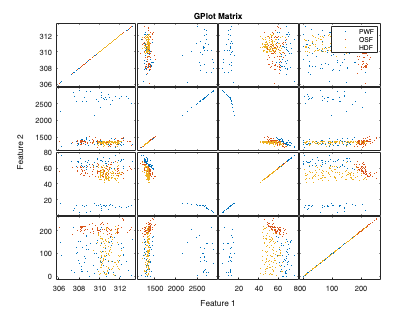

% Create a scatter plot matrix to visualize relationships between features
figure()
gplotmatrix(features, features, targetNames);
title("GPlot Matrix")
hl = xlabel("Feature 1");
currentPosition = hl.Position;
offset = -0.06;
hl.Position = [currentPosition(1), currentPosition(2) + offset, currentPosition(3)];
vl = ylabel("Feature 2");
currentPosition = vl.Position;
vl.Position = [currentPosition(1) + offset, currentPosition(2), currentPosition(3)];

**Figure 1 Caption: Scatter plot matrix visualizing pairwise relationships among the key features of the industrial predictive maintenance dataset, with points color-coded by failure type (HDF, PWF, OSF) for clear differentiation. A number of interesting feature relationships can be observed from this plot. These relationships of interest are observed more closely with the use of K-means clustering in Figure 2, below.**

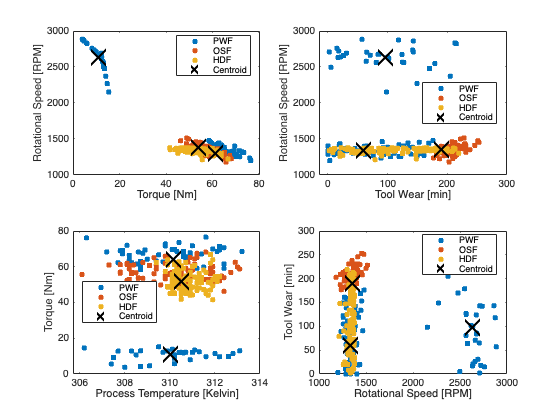

% K-means clustering visualization to explore feature relationships across different feature combinations
figure()
title("K-Means Clustering")

% Define plot configurations for different feature combinations. Each cell contains indices of features to be plotted
allPlotNums = {[3, 2], [4, 2], [1, 3], [2, 4]};

% Iterate through 4 different feature combinations
for k = 1:1:4
    % Create a 2x2 subplot grid and select the current subplot
    subplot(2, 2, k);
    % Get the feature indices for the current plot
    plotNums = allPlotNums{k};
    i = plotNums(1); 
    j = plotNums(2);
    
    % Perform K-means clustering with 3 clusters on the selected features
    [id, centroid] = kmeans(features(:, [i, j]), 3);
    % Scatter plot of data points, color-coded by original target names
    gscatter(features(:, i), features(:, j), targetNames);
    hold on
 
    % Plot cluster centroids as black 'x' markers
    plot(centroid(:, 1), centroid(:, 2), 'kx', 'LineWidth', 3, 'MarkerSize', 20, 'DisplayName', 'Centroid')
    xlabel(featuresUnits(i))
    ylabel(featuresUnits(j))
end

**Figure 2 Caption: K-Means clustering plots showcasing the relationships between selected feature pairs from the industrial predictive maintenance dataset. Data points are color-coded by original failure types—Heat Dissipation Failure (HDF), Power Failure (PWF), and Overstrain Failure (OSF). Cluster centroids are marked with black crosses to highlight grouping tendencies. These four plots were chosen for their ability to visually demonstrate clustering patterns, particularly how OSF and HDF failures tend to form distinct clusters, while PWF failures show a broader distribution, sometimes overlapping with or separating from other failure types. These suggest a more complex nature of PWF failures as compared to OSF and HDF failures.**

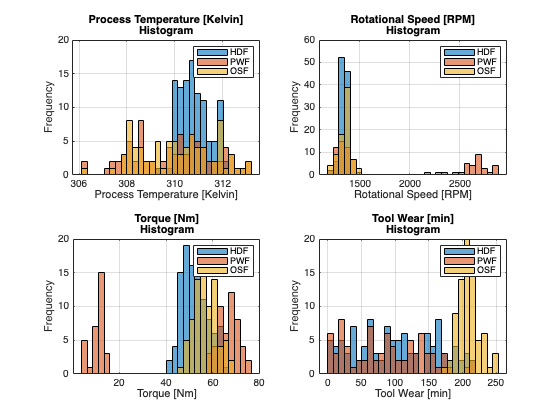


% Histogram
% Create histograms for each feature, color-coded by failure type
figure()
numBins = 30;
for i = 1:width(featuresTable)
    subplot(2, 2, i);
    
    hdfBin = hdfData(:, i); 
    pwfBin = pwfData(:, i);
    osfBin = osfData(:, i);

    % Create consistent bin edges across all histograms
    binEdges = linspace(min([hdfBin; pwfBin; osfBin]), max([hdfBin; pwfBin; osfBin]), numBins+1);
    
    % Plot overlapping histograms for each failure type
    histogram(hdfBin, 'BinEdges', binEdges, 'DisplayName', 'HDF');
    hold on;
    histogram(pwfBin, 'BinEdges', binEdges, 'DisplayName', 'PWF');
    histogram(osfBin, 'BinEdges', binEdges, 'DisplayName', 'OSF');
    
    % Add labels and formatting
    title([featuresUnits(i), "Histogram"]);
    xlabel(featuresUnits(i));
    ylabel('Frequency');
    legend;
    grid on;
end

**Figure 3 Caption: Histograms illustrating the distribution of each feature (Process Temperature, Rotational Speed, Torque, Tool Wear) across different failure types. The  overlays reveal the narrow distribution of Process Temperature for HDF, the comparitvely wider spread of Rotational Speed and Torque for PWF, and higher values of Tool Wear predominantly associated with OSF. Specifically, HDF's narrow process temperatures range and higher torque values lead to potentially insufficient heat dissipation and excessive heat generation. PWF shows an abnormaly broad distribution in rotational speed and torque, reflecting its more complex/broad failure mechanism. OSF is associated with higher tool wear and torque values, consistent with mechanical overstrain.**

## Split Data

% Randomly split data into training and testing sets using 80/20 split
% Total samples: 266, Training: 213 (80%), Testing: 53 (20%)
indices = randperm(266);
train_indicies = indices(1:213);
test_indicies = indices(214:end);

% Separate training and testing data
train_features = features(train_indicies, :);
train_targets = targetNames(train_indicies, :);
test_features = features(test_indicies, :);
test_targets = targetNames(test_indicies, :);

## Decision Tree Classification

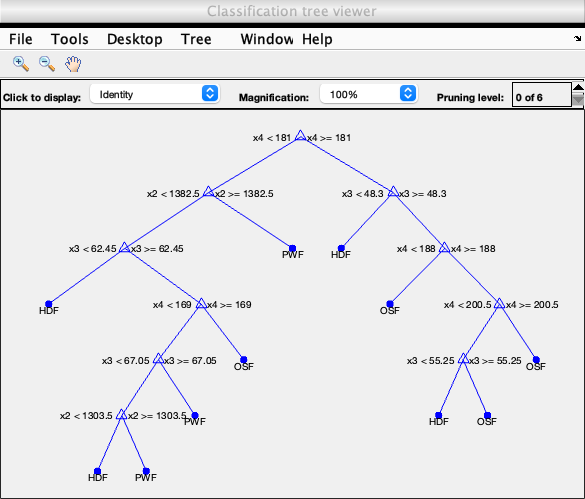

% Train a decision tree classifier
treeModel = fitctree(train_features, train_targets);
view(treeModel, Mode="graph");

**Figure 4 Caption: Decision tree structure showcasing the predictive classification of failure types (HDF, PWF, OSF) based on the industrial predictive maintenance dataset. The tree illustrates decision rules derived from features such as process temperature, rotational speed, torque, and tool wear to classify failure modes. Specifically, each node represents a decision rule splitting the data based on feature thresholds, while branches depict decision paths. Leaf nodes indicate predicted failure types. **

% Predict on test data
pred_decisionTree = treeModel.predict(test_features);

% Calculate resubstitution error (error on training data)
resubError = resubLoss(treeModel);
fprintf("Decision Tree classifier resubstitution error = %f", resubError)

Decision Tree classifier resubstitution error = 0.023474


% Perform cross-validation
cvDecisionTree = crossval(treeModel);
kfloss_decisionTree = kfoldLoss(cvDecisionTree);
fprintf("Decision Tree classifier k-fold loss = %f", kfloss_decisionTree)

Decision Tree classifier k-fold loss = 0.065728

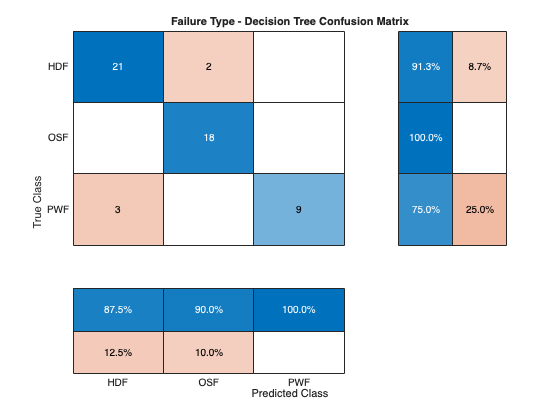


% Create confusion matrix for decision tree
figure();
cm_decisionTree = confusionchart(test_targets, string(pred_decisionTree));
cm_decisionTree.ColumnSummary = 'column-normalized';
cm_decisionTree.RowSummary = 'row-normalized';
cm_decisionTree.Title = 'Failure Type - Decision Tree Confusion Matrix';

**Figure 5 Caption: Confusion matrix for the decision tree classifier, displaying normalized row and column summaries. The matrix evaluates the performance of the model in predicting failure types on test data. **

## SVM Classification

% Train a Support Vector Machine (multi-class) classifier
svmModel = fitcecoc(train_features, train_targets);

% Perform cross-validation
cvSVM = crossval(svmModel, kfold=5);
kfloss_SVM = kfoldLoss(cvSVM);
fprintf("Support Vector Machine classifier k-fold loss = %f", kfloss_SVM)

Support Vector Machine classifier k-fold loss = 0.018779

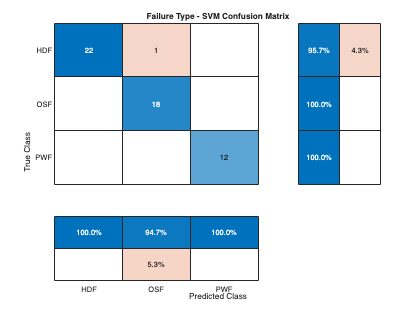


% Predict and create confusion matrix
figure();
pred_SVM = string(svmModel.predict(test_features));
cm = confusionchart(test_targets, pred_SVM);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Failure Type - SVM Confusion Matrix';

**Figure 6 Caption: Support Vector Machine (SVM) confusion matrix, normalized by rows and columns, presenting classification accuracy and misclassification patterns across failure types. From this plot, the performance of the Support Vector Machine classifier can be said to exceed the performance of the Decision Tree classifier in predicting machine failure type given the test dataset.**

## Classification Learner (Efficient Logistic Regression)

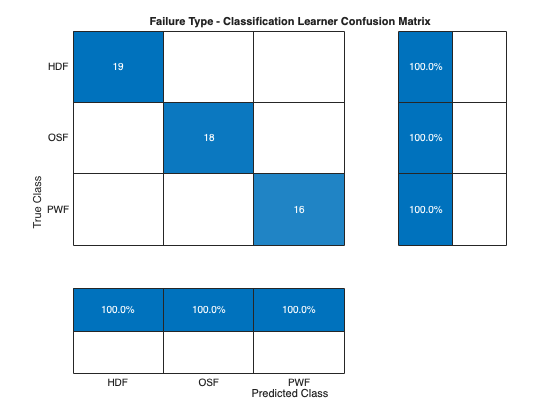

% Load a pre-trained model (Efficient Logistic Regression)
load("trainedModel.mat", "trainedModel");

% Predict using the loaded model (Efficient Logistic Regression)
[pred_ClassificationLearner, scores] = trainedModel.predictFcn(test_features);

% Create confusion matrix for Classification Learner model (Efficient Logistic Regression)
figure();
cm = confusionchart(test_targets, string(pred_ClassificationLearner));
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Failure Type - Classification Learner Confusion Matrix';

**Figure 7 Caption: Confusion matrix for the pre-trained Classification Learner model, with normalized summaries to visualize performance in predicting failure types on the test dataset. From this plot, the performance of the Efficient Logisitc Regression Classifier can be said to exceed the performance of both the Decision Tree Classifier and Support Vector Machine Classifier in predicting machine failure type given the test dataset.**

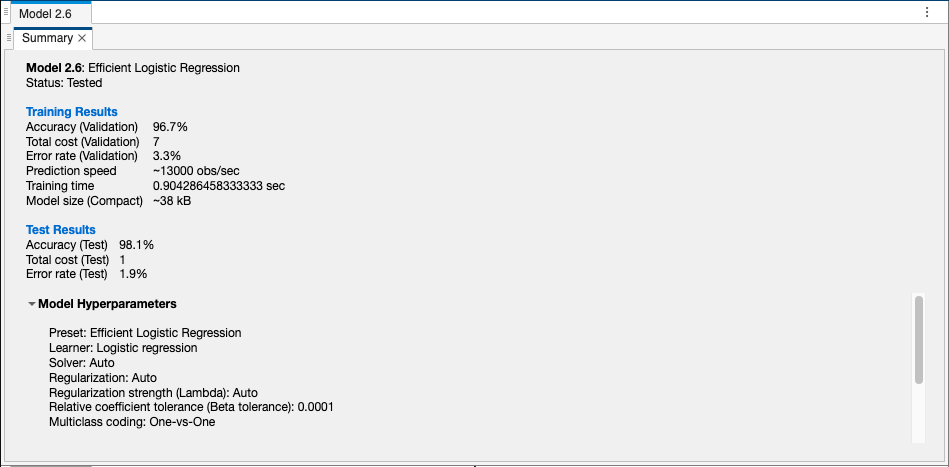

**Figure 8 Caption: Classiification Learner Toolbox summary for Model 2.6 (Efficient Logisitic Regression). This model is the best performing out of all available models in the Classification Learner Toolbox and achieves a validation accuracy of 96.7%, a validation cost of 7, a validation error rate of 3.3%,  a test accuracy of 98.1%, a test cost of 1, and an error rate of 1.9%.**

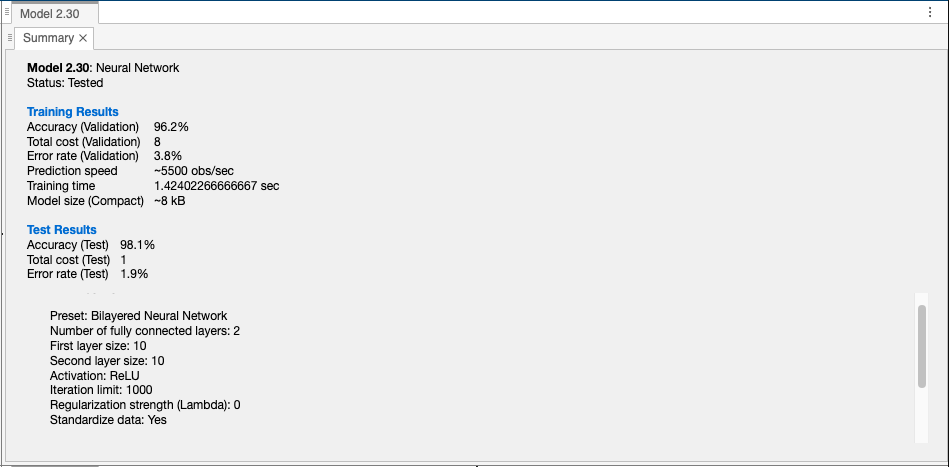

**Figure 9 Caption: Classiification Learner Toolbox summary for Model 2.30 (Neural Network). This model is the second best performing out of all available models in the Classification Learner Toolbox and achieves a validation accuracy of 96.2%, a validation cost of 8, a validation error rate of 3.8%,  a test accuracy of 98.1%, a test cost of 1, and an error rate of 1.9%. The network is bilayer and features 2 fully connected layers with 10 neurons in the both layers. The activation function is the ReLU (Rectified Linear Unit).**

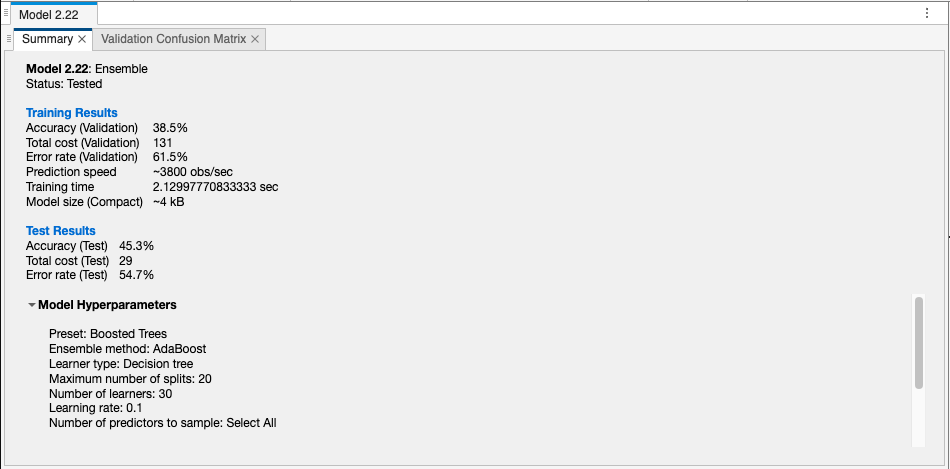

**Figure 10 Caption: Classiification Learner Toolbox summary for Model 2.22 (Boosted Trees Ensemble). This model is the worst performing out of all available models in the Classification Learner Toolbox and achieves a validation accuracy of 38.5%, a validation cost of 131, a validation error rate of 61.5%,  a test accuracy of 45.3%, a test cost of 29, and an error rate of 54.7%.**

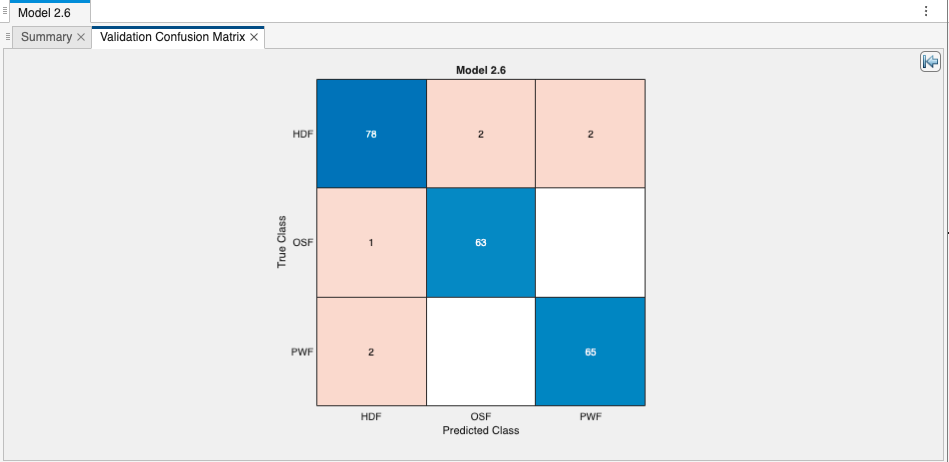

**Figure 11 Caption: Validation Confusion matrix for Model 2.6 (Efficient Logisitic Regression). As described above, this model is the best performing out of all available models in the Classification Learner Toolbox. There are a total of 213 validation datapoints. Thus, the Neural Network classified 206/213 validation datapoints correctly.**

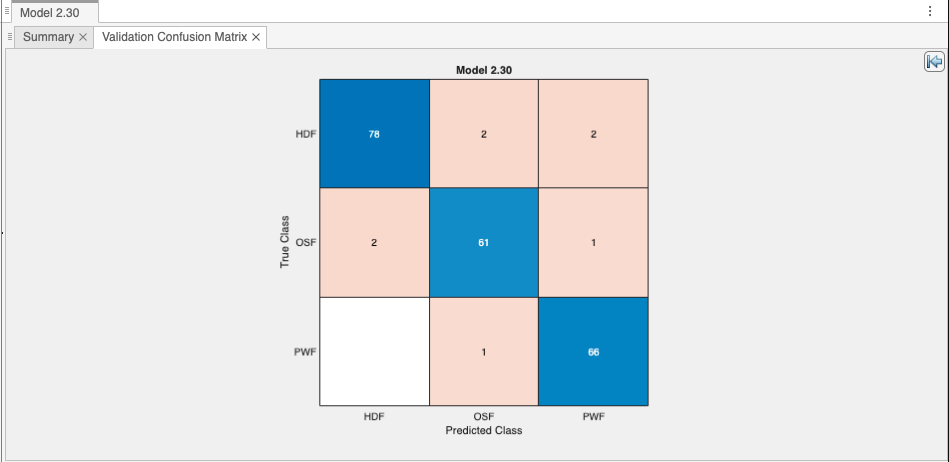

**Figure 12 Caption: Validation Confusion matrix for Model 2.30 (Neural Network). As described above, this model is the second best performing out of all available models in the Classification Learner Toolbox. There are a total of 213 validation datapoints. Thus, the Neural Network classified 205/213 validation datapoints correctly.**

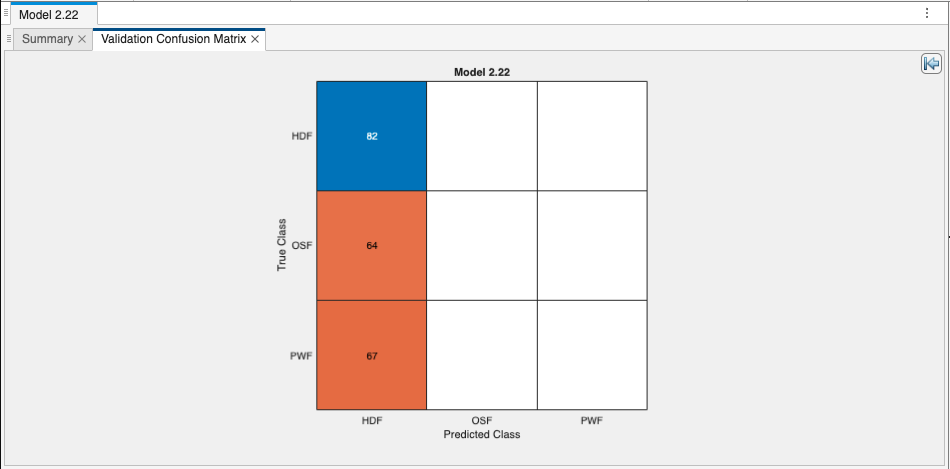

**Figure 13 Caption: Validation Confusion matrix for Model 2.22 (Boosted Trees Ensemble). As described above, this model is the worst performing out of all available models in the Classification Learner Toolbox. There are a total of 213 validation datapoints. Thus, the Boosted Trees Ensemble classified only 82/213 validation datapoints correctly.**

## Conclusion

This project analyzed the AI4I 2020 Predictive Maintenance Dataset to classify machine failure types. The initial data exploration involved scatter plots, k-means clustering, and histograms to understand feature distributions and relationships. This exploration provided the basic analysis necessary to reveal trends in how process temperature, rotational speed, torque, and tool wear vary with different failure types: Heat Dissipation Failure (HDF), Power Failure (PWF), and Overstrain Failure (OSF). This exploration showed distinct relationships between features and failure types. HDF was linked to narrow process temperature ranges, PWF showed variability in speed and torque, and OSF was associated with higher tool wear. The visualizations and analyses guided the model selection and evaluation, summarized below.

The next phase involved model investigation. The K-Nearest Neighbors (KNN) classifier was tested during model selection but performed poorly on both the train and test datasets, so it was not used further. Instead, Decision Tree and Support Vector Machine (SVM) models were implemented, as they provided better classification performance. The Decision Tree model achieved a resubstitution error of around 5.6% and a k-fold loss of around 8.9%. The SVM model outperformed it with a k-fold loss of 3.3%. Finally, the Efficient Logistic Regression classifier, selected from the Classification Learner Toolbox, provided the best results with a test accuracy of 98.1% and a test error rate of 1.9%.